% Presetting
syms x y z omega phi psi;
PosExtract=[0; 0; 0; 1];
p(x, y, z)=[x; y; z];
Rotx(omega)=[1  0   0
            0   cos(omega)  -sin(omega)
            0   sin(omega)  cos(omega)];
Roty(phi)=[cos(phi) 0   sin(phi)
            0   1   0
            -sin(phi)   0   cos(phi)];
Rotz(psi)=[cos(psi) -sin(psi)   0
            sin(psi)    cos(psi)    0
            0   0   1];

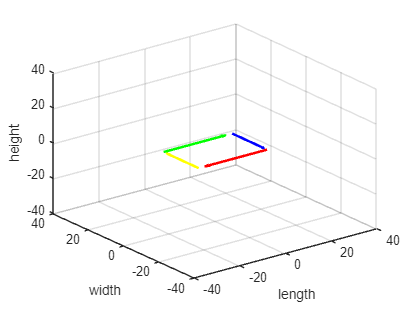

% Body Kinematics test by plot graph

% Global to Body
anglegax=0;
anglegay=0;
anglegaz=0;
pga=[0 0 0].';
Rotga=Rotx(anglegax)*Roty(anglegay)*Rotz(anglegaz);
Tga=HomogeneousTransform(Rotga, pga, 1);

% Align to Body
angleamx=sym(pi)/2;
angleamy=0;
angleamz=0;
pam=[0 0 0].';
Rotam=Rotx(angleamx)*Roty(angleamy)*Rotz(angleamz);
Tam=HomogeneousTransform(Rotam, pam, 1);

Tgm=Tga*Tam;

% Body to Right Front Shoulder
anglemRFS=pi/2;
pmRFS=[30/2 0 20/2].';
RotmRFS=Roty(anglemRFS);
TmRFS=HomogeneousTransform(RotmRFS, pmRFS, 1);

% Body to Right Back Shoulder
anglemRBS=pi/2;
pmRBS=[-30/2 0 20/2].';
RotmRBS=Roty(anglemRBS);
TmRBS=HomogeneousTransform(RotmRBS, pmRBS, 1);

% Body to Left Front Shoulder
anglemLFS=-pi/2;
pmLFS=[30/2 0 -20/2].';
RotmLFS=Roty(anglemLFS);
TmLFS=HomogeneousTransform(RotmLFS, pmLFS, 1);

% Body to Left Back Shoulder
anglemLBS=-pi/2;
pmLBS=[-30/2 0 -20/2].';
RotmLBS=Roty(anglemLBS);
TmLBS=HomogeneousTransform(RotmLBS, pmLBS, 1);

TgRFS=Tgm*TmRFS;
TgRBS=Tgm*TmRBS;
TgLFS=Tgm*TmLFS;
TgLBS=Tgm*TmLBS;

pgRFS=TgRFS*PosExtract;
pgRBS=TgRBS*PosExtract;
pgLFS=TgLFS*PosExtract;
pgLBS=TgLBS*PosExtract;

front=pgRFS-pgLFS;
right=pgRBS-pgRFS;
back=pgLBS-pgRBS;
left=pgLFS-pgLBS;

figure
quiver3(pgLFS(1,1), pgLFS(2,1), pgLFS(3,1), front(1,1), front(2,1), front(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(pgRFS(1,1), pgRFS(2,1), pgRFS(3,1), right(1,1), right(2,1), right(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(pgRBS(1,1), pgRBS(2,1), pgRBS(3,1), back(1,1), back(2,1), back(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(pgLBS(1,1), pgLBS(2,1), pgLBS(3,1), left(1,1), left(2,1), left(3,1), 'Color', 'green','LineWidth', 2)
hold on
xlabel('length')
ylabel('width')
zlabel('height')
axis([-40 40 -40 40 -40 40])

% Right Front Leg Kinematics test by plot graph

% Right Front Shoulder to Preprocessing UpperArm
angle01=0;
p01=p(0,0,10);
Rot01=Rotz(angle01);
T01=HomogeneousTransform(Rot01, p01, 1);

% Right Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;
angle12x=pi/2;
p12=p(0, 0, 0);
Rot12=Rotz(angle12z)*Rotx(angle12x);
T12=HomogeneousTransform(Rot12, p12, 1);

% Right Front UpperArm to LowArm
angle23=-pi/6;
p23=p(20*cos(-pi/6),20*sin(-pi/6),10);
Rot23=Rotz(angle23);
T23=vpa(HomogeneousTransform(Rot23, p23, 1));

% Right Front LowArm to Foot
angle34=pi/3;
p34=p(20*cos(pi/3),20*sin(pi/3),0);
Rot34=Rotz(angle34);
T34=vpa(HomogeneousTransform(Rot34, p34, 1))

$$T34 = \left(\begin{array}{cccc} 0.5 & -0.86602540378443864676372317075294 & 0 & 10.0\\ 0.86602540378443864676372317075294 & 0.5 & 0 & 17.320508075688772935274463415059\\ 0 & 0 & 1.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

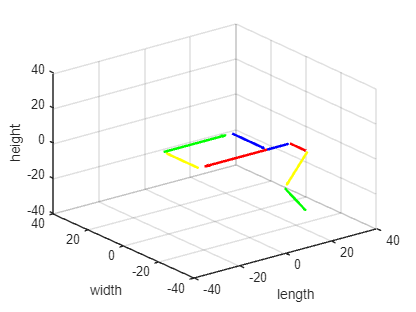


% Right Front Shoulder to UpperArm
T02=T01*T12;
% Right Front Shoulder to LowArm
T03=T02*T23;
% Right Front Shoulder to Foot
T04=T03*T34;

pgRFU=TgRFS*T01*PosExtract;
pgRFL1=TgRFS*T02*[0 0 10 1].';
pgRFL2=TgRFS*T03*PosExtract;
pgRFF=TgRFS*T04*PosExtract;

RFS=pgRFU-pgRFS;
RFU=pgRFL1-pgRFU;
RFL1=pgRFL2-pgRFL1;
RFL2=pgRFF-pgRFL2;

quiver3(pgRFS(1,1), pgRFS(2,1), pgRFS(3,1), RFS(1,1), RFS(2,1), RFS(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(pgRFU(1,1), pgRFU(2,1), pgRFU(3,1), RFU(1,1), RFU(2,1), RFU(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(pgRFL1(1,1), pgRFL1(2,1), pgRFL1(3,1), RFL1(1,1), RFL1(2,1), RFL1(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(pgRFL2(1,1), pgRFL2(2,1), pgRFL2(3,1), RFL2(1,1), RFL2(2,1), RFL2(3,1), 'Color', 'green','LineWidth', 2)
hold on
xlabel('length')
ylabel('width')
zlabel('height')
axis([-40 40 -40 40 -40 40])

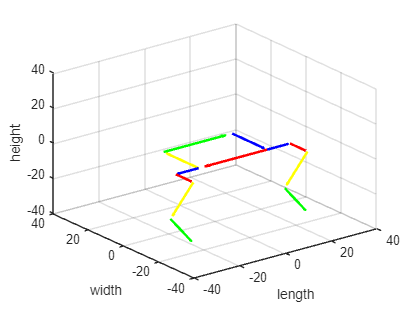

% Right Back Leg Kinematics test by plot graph

% Right Back Shoulder to Preprocessing UpperArm
angle01=0;
p01=p(0,0,-10);
Rot01=Rotz(angle01);
T01=HomogeneousTransform(Rot01, p01, 1);

% Right Back Preprocessing UpperArm to UpperArm
angle12z=-pi/2;
angle12x=pi/2;
p12=p(0, 0, 0);
Rot12=Rotz(angle12z)*Rotx(angle12x);
T12=HomogeneousTransform(Rot12, p12, 1);

% Right Back UpperArm to LowArm
angle23=-pi/6;
p23=p(20*cos(-pi/6),20*sin(-pi/6),10);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1);

% Right Back LowArm to Foot
angle34=pi/3;
p34=p(20*cos(pi/3),20*sin(pi/3),0);
Rot34=Rotz(angle34);
T34=HomogeneousTransform(Rot34, p34, 1);

% Right Back Shoulder to UpperArm
T02=T01*T12;
% Right Back Shoulder to LowArm
T03=T02*T23;
% Right Back Shoulder to Foot
T04=T03*T34;

pgRBU=TgRBS*T01*PosExtract;
pgRBL1=TgRBS*T02*[0 0 10 1].';
pgRBL2=TgRBS*T03*PosExtract;
pgRBF=TgRBS*T04*PosExtract;

RBS=pgRBU-pgRBS;
RBU=pgRBL1-pgRBU;
RBL1=pgRBL2-pgRBL1;
RBL2=pgRBF-pgRBL2;

quiver3(pgRBS(1,1), pgRBS(2,1), pgRBS(3,1), RBS(1,1), RBS(2,1), RBS(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(pgRBU(1,1), pgRBU(2,1), pgRBU(3,1), RBU(1,1), RBU(2,1), RBU(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(pgRBL1(1,1), pgRBL1(2,1), pgRBL1(3,1), RBL1(1,1), RBL1(2,1), RBL1(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(pgRBL2(1,1), pgRBL2(2,1), pgRBL2(3,1), RBL2(1,1), RBL2(2,1), RBL2(3,1), 'Color', 'green','LineWidth', 2)
hold on
xlabel('length')
ylabel('width')
zlabel('height')
axis([-40 40 -40 40 -40 40])

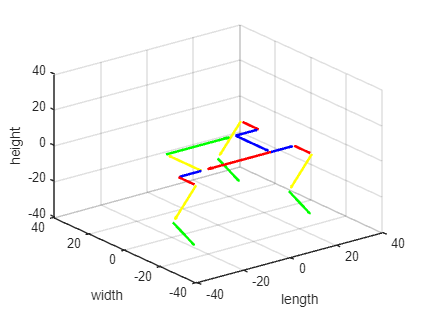

% Left Front Leg Kinematics test by plot graph

% Left Front Shoulder to Preprocessing UpperArm
angle01=0;
p01=p(0,0,-10);
Rot01=Rotz(angle01);
T01=HomogeneousTransform(Rot01, p01, 1);

% Left Front Preprocessing UpperArm to UpperArm
angle12z=-pi/2;
angle12x=-pi/2;
p12=p(0, 0, 0);
Rot12=Rotz(angle12z)*Rotx(angle12x);
T12=HomogeneousTransform(Rot12, p12, 1);

% Left Front UpperArm to LowArm
angle23=-pi/6;
p23=p(20*cos(-pi/6),20*sin(-pi/6),-10);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1);

% Left Front LowArm to Foot
angle34=pi/3;
p34=p(20*cos(pi/3),20*sin(pi/3),0);
Rot34=Rotz(angle34);
T34=HomogeneousTransform(Rot34, p34, 1);

% Left Front Shoulder to UpperArm
T02=T01*T12;
% Left Front Shoulder to LowArm
T03=T02*T23;
% Left Front Shoulder to Foot
T04=T03*T34;

pgLFU=TgLFS*T01*PosExtract;
pgLFL1=TgLFS*T02*[0 0 -10 1].';
pgLFL2=TgLFS*T03*PosExtract;
pgLFF=TgLFS*T04*PosExtract;

LFS=pgLFU-pgLFS;
LFU=pgLFL1-pgLFU;
LFL1=pgLFL2-pgLFL1;
LFL2=pgLFF-pgLFL2;

quiver3(pgLFS(1,1), pgLFS(2,1), pgLFS(3,1), LFS(1,1), LFS(2,1), LFS(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(pgLFU(1,1), pgLFU(2,1), pgLFU(3,1), LFU(1,1), LFU(2,1), LFU(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(pgLFL1(1,1), pgLFL1(2,1), pgLFL1(3,1), LFL1(1,1), LFL1(2,1), LFL1(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(pgLFL2(1,1), pgLFL2(2,1), pgLFL2(3,1), LFL2(1,1), LFL2(2,1), LFL2(3,1), 'Color', 'green','LineWidth', 2)
hold on
xlabel('length')
ylabel('width')
zlabel('height')
axis([-40 40 -40 40 -40 40])

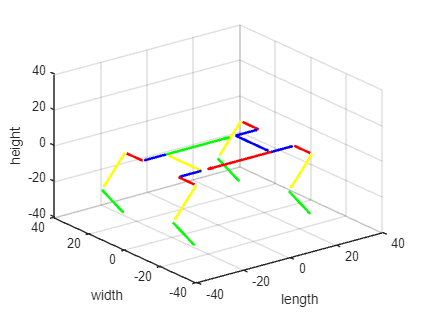

% Left Back Leg Kinematics test by plot graph

% Left Back Shoulder to Preprocessing UpperArm
angle01=0;
p01=p(0,0,10);
Rot01=Rotz(angle01);
T01=HomogeneousTransform(Rot01, p01, 1);

% Left Back Preprocessing UpperArm to UpperArm
angle12z=-pi/2;
angle12x=-pi/2;
p12=p(0, 0, 0);
Rot12=Rotz(angle12z)*Rotx(angle12x);
T12=HomogeneousTransform(Rot12, p12, 1);

% Left Back UpperArm to LowArm
angle23=-pi/6;
p23=p(20*cos(-pi/6),20*sin(-pi/6),-10);
Rot23=Rotz(angle23);
T23=HomogeneousTransform(Rot23, p23, 1);

% Left Back LowArm to Foot
angle34=pi/3;
p34=p(20*cos(pi/3),20*sin(pi/3),0);
Rot34=Rotz(angle34);
T34=HomogeneousTransform(Rot34, p34, 1);

% Left Back Shoulder to UpperArm
T02=T01*T12;
% Left Back Shoulder to LowArm
T03=T02*T23;
% Left Back Shoulder to Foot
T04=T03*T34;

pgLBU=TgLBS*T01*PosExtract;
pgLBL1=TgLBS*T02*[0 0 -10 1].';
pgLBL2=TgLBS*T03*PosExtract;
pgLBF=TgLBS*T04*PosExtract;

LBS=pgLBU-pgLBS;
LBU=pgLBL1-pgLBU;
LBL1=pgLBL2-pgLBL1;
LBL2=pgLBF-pgLBL2;

quiver3(pgLBS(1,1), pgLBS(2,1), pgLBS(3,1), LBS(1,1), LBS(2,1), LBS(3,1), 'Color', 'blue','LineWidth', 2)
hold on
quiver3(pgLBU(1,1), pgLBU(2,1), pgLBU(3,1), LBU(1,1), LBU(2,1), LBU(3,1), 'Color', 'red','LineWidth', 2)
hold on
quiver3(pgLBL1(1,1), pgLBL1(2,1), pgLBL1(3,1), LBL1(1,1), LBL1(2,1), LBL1(3,1), 'Color', 'yellow','LineWidth', 2)
hold on
quiver3(pgLBL2(1,1), pgLBL2(2,1), pgLBL2(3,1), LBL2(1,1), LBL2(2,1), LBL2(3,1), 'Color', 'green','LineWidth', 2)
xlabel('length')
ylabel('width')
zlabel('height')
axis([-40 40 -40 40 -40 40])